load and initialize

addpath myFunction\myftn
clearvars -except mapCD
fn = 'RawData\1T-TaS2(point defect)\mapCD.mat'

fn = 'RawData\1T-TaS2(point defect)\mapCD.mat'

loadif(fn)

fldNm = 1×1 cell array
    {'mapCD'}



Your variables are:

fldNm  fn     mt     



ans = 'already'

## Calculate historam Energy-wise histogram

V = mapCD.V;
edges = -0.01:0.0001:0.14

edges =    -0.0100   -0.0099   -0.0098   -0.0097   -0.0096   -0.0095   -0.0094   -0.0093   -0.0092   -0.0091   -0.0090   -0.0089   -0.0088   -0.0087   -0.0086   -0.0085   -0.0084   -0.0083   -0.0082   -0.0081   -0.0080   -0.0079   -0.0078   -0.0077   -0.0076   -0.0075   -0.0074   -0.0073   -0.0072   -0.0071   -0.0070   -0.0069   -0.0068   -0.0067   -0.0066   -0.0065   -0.0064   -0.0063   -0.0062   -0.0061   -0.0060   -0.0059   -0.0058   -0.0057   -0.0056   -0.0055   -0.0054   -0.0053   -0.0052   -0.0051


dosHolder =  zeros(length(V),length(edges)-1,2);
for ip = 1:2
    for iv = 1:length(V)
        nowConductance = mapCD.dt(ip).G(:,:,iv);
        nowConductance = nowConductance(:);
        N = histcounts(nowConductance,edges);
        dosHolder(iv,:,ip) = N;
    end
end

## Visualize Energy-wise histogram

gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(3,:),[0 0 .5 .3]);
f1.Visible = "on";

Visualization 1: single case

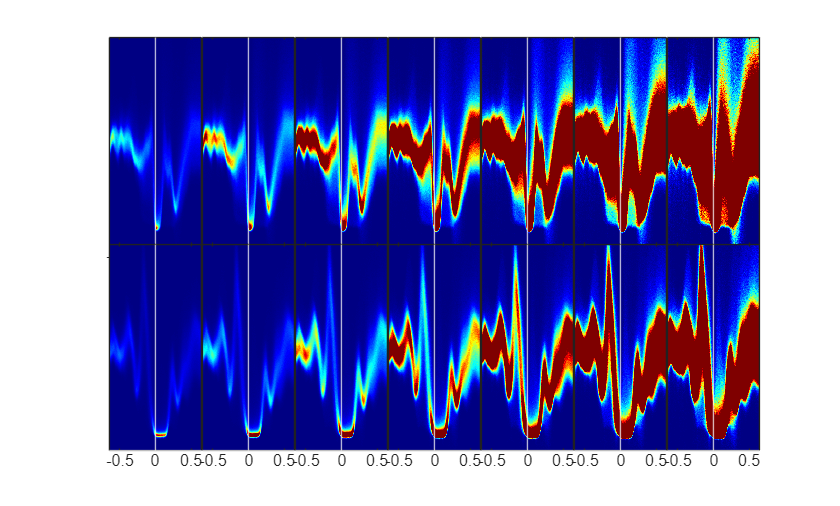

saturationFactor = 1

saturationFactor = 0.5000

saturationFactor = 0.2500

saturationFactor = 0.1250

saturationFactor = 0.0625

saturationFactor = 0.0312

saturationFactor = 0.0156

saturationFactor = 1

saturationFactor = 0.5000

saturationFactor = 0.2500

saturationFactor = 0.1250

saturationFactor = 0.0625

saturationFactor = 0.0312

saturationFactor = 0.0156

msb = 2;
nsb = 7;
nms = ["T_C" "T_A"];
tiledlayout(msb,nsb,'TileSpacing','none')
% for indPower = 1:msb*nsb
for isb = 1:msb
    for jsb = 1:nsb
        nexttile
        saturationFactor = (1/2)^(jsb-1)
        im = drawVhis(dosHolder(:,:,isb),V);
        im.Parent.XLim = [-1 1]*0.65;
        im.Parent.CLim = im.Parent.CLim*saturationFactor;
        xline(0,'w')
        yline(0,'w')
        colormap jet
    end
end

## Save data

vDos.dt = dosHolder;
vDos.edges = edges;
vDos.binCntr = (edges(1:end-1) + edges(2:end))/2;
vDos.hd = currentScript

vDos = struct with fields:
         dt: [1521×1500×2 double]
      edges: [-0.0100 -0.0099 -0.0098 -0.0097 -0.0096 -0.0095 -0.0094 -0.0093 -0.0092 -0.0091 -0.0090 -0.0089 -0.0088 -0.0087 -0.0086 -0.0085 -0.0084 -0.0083 -0.0082 -0.0081 -0.0080 -0.0079 -0.0078 -0.0077 -0.0076 -0.0075 -0.0074 … ] (1×1501 double)
    binCntr: [-0.0100 -0.0099 -0.0097 -0.0097 -0.0095 -0.0095 -0.0094 -0.0093 -0.0092 -0.0091 -0.0089 -0.0089 -0.0088 -0.0086 -0.0086 -0.0084 -0.0083 -0.0083 -0.0082 -0.0080 -0.0080 -0.0078 -0.0077 -0.0077 -0.0075 -0.0075 -0.0074 … ] (1×1500 double)
         hd: 'D:\od\OneDrive\matlab\Scripts\1T-TaS2(pointDefect)\d2024_01_20__19_00_continuousHistogram.mlx'


save RawData\'1T-TaS2(point defect)'\vDos.mat vDos

function im = drawVhis(vhis,V,dos)
% colormap jet
views(vhis)
ax = gca();
yticks([]);
im = findobj(ax,'Type','image');
im.XData = V;
axis normal
end